# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Função a ser ajustada

syms x
%Número de coeficientes a serem calculados
dgf=3;
% Vetor dos coeficientes
a = sym('a',[1 dgf]);
%Função de ajuste de curva
f= a(1)*x + a(2)*sin(x*a(3));

Pontos para ajuste

%vetores com os input;
yp = [1.4 3.1 1.1 5.8 3.2 4 6.1 5.1 -0.1 7.5 4 1.9 3 0.5 -3.8];
xp = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15];
l=length(xp);

Função Erro

syms E
E=0;
for k=1:l
    E=E+(yp(k)-subs(f,x,xp(k)))^2;
end

Cálculo do gradiente e Hessiana do Erro:

Grad_E=gradient(E,a);
J=jacobian(Grad_E,a);

Solução do sistema em relação a a_0, a_1 e a_2

Incertezas limitantes relativas a:

- e1 -> Tamanho do Intervalo trabalhado

- e2 -> Resíduo do valor da função no ponto

e1=10^-3;
e2=10^-3;

Número de interações

Int_max=200;

Chute inicial de uma raiz para o método de Newton-Raphson (Perde um pouco a ideia do que chutar)

m=[1,1,1];

Número de dígitos para a precisão do problema:

digits(5)

Loop

k=0;
while k<Int_max 
        fi=subs(Grad_E,a,m);
    if norm(fi)<e1
        break
    end
        Ji=subs(J,a,m);
    k=k+1;
    if norm(fi)>e1
        %Raiz calculada atráves do método de newton raphson
        m=m+linsolve(vpa(Ji),vpa(-fi))';
    end
end

Cálculo do número de iterações para a achar os coeficientes do ajuste

fmt = ['A solução é: [', repmat('%g, ', 1, numel(m)-1), '%g] com %d interações'];
fprintf(fmt, m, k)

A solução é: [0.245653, -1.26898, 0.968897] com 6 interações

Plotagem dos pontos dados e do ajuste que foi calculado

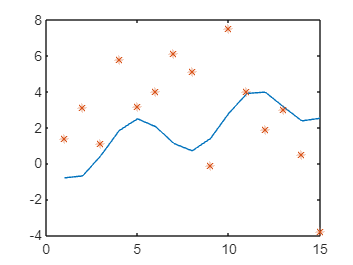

yplot=subs(subs(f,a,m),x,xp);
ypplot=double(vpa(yplot));
plot(xp,yplot)
hold on
plot(xp,yp,'*')

Cálculo do R^2 (ccoeficiente de Pearson)

coor=corrcoef(yp,(ypplot))

coor =     1.0000    0.0293
    0.0293    1.0000


R=coor(1,2)^2

R = 8.5888e-04